# Craig's robotics book and learning from Robotics toolbox interactive script

2025 Oct 27 MatLab practice from chap 1 to 4

## Chap 2 Mapping and  other transforms

### 2.1 Rotation with 3D co-ordinate, based on an axis (z) using directional cosine projection

- 
$$^A_B R = \left[
\matrix{\hat{x}_B \cdot \hat{x}_A & \hat{y}_B \cdot \hat{x}_A & \hat{z}_B \cdot \hat{x}_A \cr 
\hat{x}_B \cdot \hat{y}_A & \hat{y}_B \cdot \hat{y}_A & \hat{z}_B \cdot \hat{y}_A \cr
\hat{x}_B \cdot \hat{z}_A & \hat{y}_B \cdot \hat{z}_A & \hat{z}_B \cdot \hat{z}_A }
\right]
=\left[
\matrix{^{A}\hat{x}_B & ^{A}\hat{y}_B & ^{A}\hat{z}_B}
\right]
=\left[
\matrix{^{B}\hat{x}_A^T & ^{B}\hat{y}_A^T & ^{B}\hat{z}_A^T}
\right]$$


- 
$$^{A}_BR = ^{B}_AR^T = ^{B}_AR^{-1}$$


-    $^{A}p_x = ^{B}\hat{x}_A \cdot ^{B}p$, $^{A}p_y = ^{B}\hat{y}_A \cdot ^{B}p$, $^{A}p_z = ^{B}\hat{z}_A \cdot ^{B}p$

#### Example 2.1:

3D Euler frame A: $\{A\} = \left[
\matrix{ \hat{x}_A & \hat{y}_A & \hat{z}_A}
\right]$, $\hat{x}_A = \left[ \matrix{1 & 0 & 0} \right]^T$ and $\hat{y}_A = \left[ \matrix{0 & 1 & 0} \right]^T$, and $\hat{z}_A = \left[ \matrix{0 & 0 & 1} \right]^T$.

3D Euler fram B: rotate about axis Z, where $\hat{z}_A = \hat{z}_B$, counter clock wise for $\theta = 30^o$

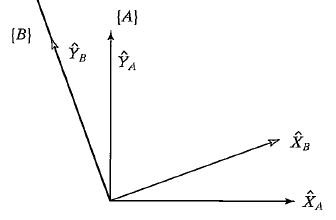

$^A_BR = \left [
\matrix{\cos{30} & -\sin{30} & 0 \cr \sin{30} & \cos{30} &0 \cr 0 & 0  & 1}
\right]$, thus $\{B\} = \left[ \matrix{
\sqrt{3}/2 & -1/2 & 0 \cr 
1/2 & \sqrt{3}/2 & 0 \cr 
0 & 0 & 1
}\right]$, as $\hat{x}_B = \left[ \matrix{ 
\sqrt{3}/2 \cr
1/2 \cr
0
}\right]$, specifically it is $^A\hat{x}_B$. $\hat{y}_B = \left[ \matrix{ 
-1/2 \cr
\sqrt{3}/2 \cr
0
}\right]$

Note that the first, second and third row is $^B\hat{x}_A ^T= \left[\matrix{
\sqrt{3}/2 & -1/2 &0
}\right] $, $^B\hat{y}_A ^T= \left[\matrix{
1/2 & \sqrt{3}/2 & 0
}\right] $, and $^B\hat{z}_A ^T= \left[\matrix{
0 & 0 & 1
}\right] $

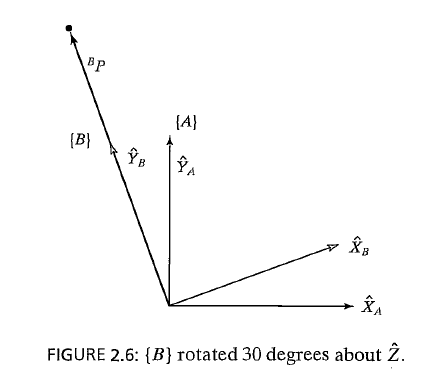

If we have a point p that is fixed in space, but only rotate the frame from frame:$\{A\}$ to frame: $\{B\}$, given $^{B}p = \left[ \matrix{
0 \cr 
2 \cr
0
}\right]$ assigned with this vector on against frame B. then for 


$$^{A}p = \left[ \matrix{
p_x \cr
p_y \cr
p_z
}\right] = 
 \left[ \matrix{
-1 \cr
\sqrt{3} \cr
0
}\right]=
\left[ \matrix{
\cos{30} & -\sin{30} & 0 \cr
\sin{30} & \cos{30} & 0 \cr
0 & 0 & 1
}\right]
\left[\matrix{
0 \cr
2 \cr
0
}\right]$$


% code example of using a rotational matrix from euler angles: eul
% eul2rotm([1/3*pi/2 0 0])   % remember in MatLab, euler is z-y-x!!!
% The above example of calculating:
p_frameB = [0 2 0]'     % point vector (translation vector) only in three numerals, not distinquishable

p_frameB =      0
     2
     0


p_frameA = eul2rotm([1/3*pi/2 0 0])*p_frameB    % practicing call direct use of eul2rotm (euler angle to rotational matrix) function

p_frameA =    -1.0000
    1.7321
         0


If we have a fixed point in space, and need just the translation... it is done directly by

p_frameA = [0 2 0]' + [3 1 0]'

p_frameA =      3
     3
     0



clear p*    % the above is example 2.1 on page 26 in Craig's book.

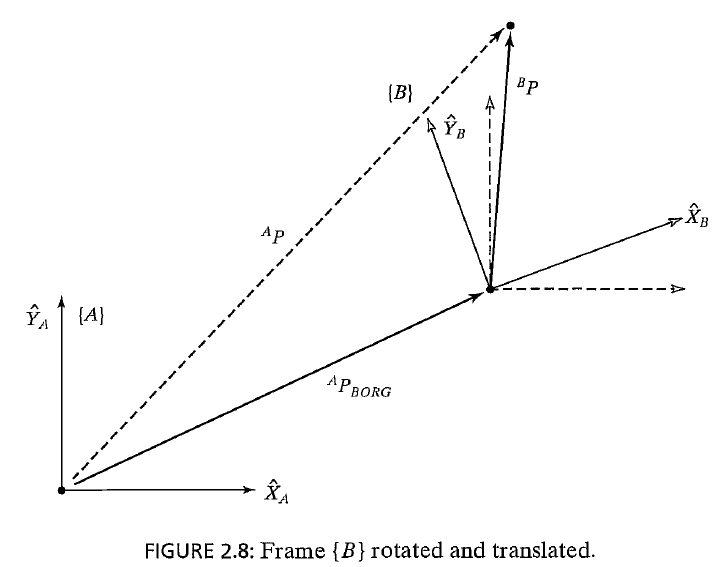

% using transformation operator to find directly the ^Ap presented if given
% ^Bp as like the example 2.2 on page 29
p_frameB = [3 7 0]';
p_Borg = [10 5 0]';   % frameB origin
frameB_orientation = se3([30/180*pi 0 0],'eul').rotm();
T_ab = se3(frameB_orientation,p_Borg') 

T_ab = se3
    0.8660   -0.5000         0   10.0000
    0.5000    0.8660         0    5.0000
         0         0    1.0000         0
         0         0         0    1.0000


p_frameA = T_ab.tform*([p_frameB' 1]');
p_frameA = p_frameA(1:3)

p_frameA =     9.0981
   12.5622
         0



clear all

### 2.2 Translation with rotation becomes transformation

using standard vector addition: $^A p = ^ B p + ^A p_{BORG}$, as BORG= B's orgin

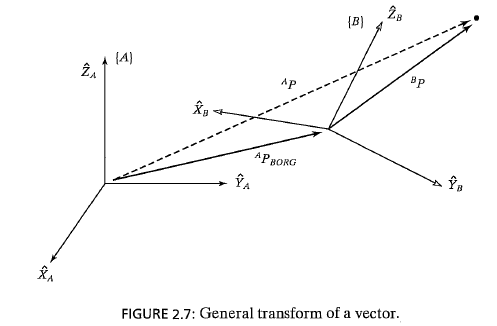

Since $^B p = ^A _B R ^B p$, then $^A p = ^A _B R ^B p + ^A p_{BORG}$ can be made into a general mapping from one frame making it:


$$\left[ \matrix{
^A p \cr
1
}\right] = \left[\matrix{
^A _B R & ^A p_{BORG} \cr
0,0,0 & 1
}\right] = \left[\matrix{
^B p \cr
1
}\right]$$


If using Euler-angle presentation $(\hat{x} -\hat{y}-\hat{z}, \alpha-\beta-\gamma)$


$$R_x \left(\alpha \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \alpha  & -\sin \alpha \\
0 & \sin \alpha  & \cos \alpha 
\end{array}\right\rbrack$$
 
$$R_y \left(\beta \right)=\left\lbrack \begin{array}{ccc}
\cos \beta  & 0 & \sin \beta \\
0 & 1 & 0\\
-\sin \beta  & 0 & \cos \beta 
\end{array}\right\rbrack$$
 
$$R_z \left(\gamma \right)=\left\lbrack \begin{array}{ccc}
\cos \gamma  & -\sin \gamma  & 0\\
\sin \gamma  & \cos \gamma  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


can be used to combine into a local orentation R matrix.

Also, by convention, it is normal to put only one zero under the $^A_BR$ 3 by 3 matrix.

#### Example 2.2: ploting and exercise using the most of robotics toolbox with pre-defined object

% example for defining a new frame and plot using the plotframe.m function

disp('Using universal frame as {A}, please input new frame origin: (x, y, z)')

Using universal frame as {A}, please input new frame origin: (x, y, z)


% newFrameOrigin = input('Enter the new frame origin as a vector [x, y, z]'': ');
newFrameOrigin = [3 14 0]

newFrameOrigin =      3    14     0


% Define the directional cosines for the transformation
% dirCos = eye(3); % Identity matrix as an example for no rotation

disp('Needs new frame {B} orientation, try to make it orthnormal, or can rotate it by providing random ZYX axis order which is also denoted as "Roll Pitch Yaw (rpy)."')

Needs new frame {B} orientation, try to make it orthnormal, or can rotate it by providing random ZYX axis order which is also denoted as "Roll Pitch Yaw (rpy)."


% disp('https://www.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html')


The following the code is from "plotframe" downloaded from MatLab center 

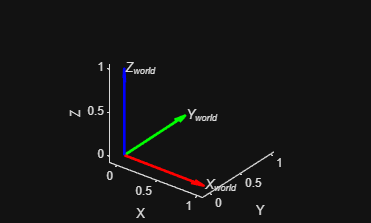

figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe( 'LabelBasis', true, ...
    'Labels', {'X_{world}','Y_{world}','Z_{world}'}, ...
    'TextProperties', {'FontAngle','italic'} )
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded

Using robotics toolbox object SE2, SE3 or other euler angles for tranformation:

% se3 for orientation with position in 3D (declare a frame f1, f2... etc)
% so3 for orientation only, remember orientation is with 3 by 3 matrix
% (decalre a orentation, o1, o2... etc, this time using Euler angles)
% against 3D normal world frame.

% position is either p1, p2... etc [0 3 1] or [0;3;1] etc
% euler angles either eul1, eul2, associated at p1, p2 points

eul1 = [0 0 0];  % euler angle in z-y-x rotation sequence, roll-pitch-yaw
eul2 = 2*pi*rand(1,3);  % second rotation

p1 = newFrameOrigin;
p2 = [3 14 5];

f1 = se3(eul1,"eul",p1)      % f1 frame object created by orientation eul1 and point p1 

f1 = se3
     1     0     0     3
     0     1     0    14
     0     0     1     0
     0     0     0     1


f2 = se3(eul2,"eul",p2)

f2 = se3
   -0.9681    0.2165   -0.1259    3.0000
    0.0100    0.5357    0.8444   14.0000
    0.2502    0.8162   -0.5208    5.0000
         0         0         0    1.0000


plot the same figure so to show the new frames "f1", and "f2" at locations "p1" and "p2".

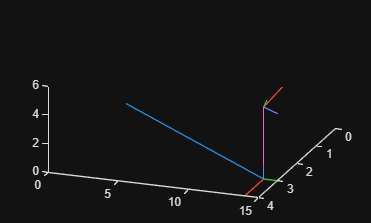

figure
hold on
%axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
%rot = rotm(f1)           % rotm = extract rotational matrix from object "r" 
%plotframe('LabelBasis', true)   % using plotframe to have standard basis (feels like having eul0, p0, f0)
plotTransforms(f1)      % one can use plotTransform to plot 3D may be "un-rationed"

plotTransforms(f2)
plotline(p1,p2)
plotline([0 0 0],p1)    % calling personal function plotline.m (later) so to use similar way like plotframe.m
hold off

All the above scripts are using the most of Robotics toolbox, as using its opject to make a frame objects, and then using rotm(SE3) to extract rotation matrix, using trvec(SE3)  to extract tranlation matrix, and tform(SE3) to extract homogeneous tranformation. One more concept also uses quaternion $(a+b\hat{i}+c\hat{j}+d\hat{k})$, which is also a shorthand notation to present a full orientation for a "frame". It still needs a "position".

% remember: rotm = rotational_Matrix, trvec = translation_vector.
% it is a function from tranformation.rotm, and many others inside the se3
% object, that can be checked with "help se3"

% in Aerospace toolbox, there is a randrot(m) function, that can be used to
% make a randomized quaternion, or we can make random number angles in 2pi
% and random positions in 3D.
p = [zeros(3,1) round(10*rand(3,2))]    % location points vector {p} 3 by n, now in translation vector rows...

p =      0     6     3
     0     2     5
     0     8     7


q =[quaternion(0,0,0,0) randrot(1,2)];  % making quaternion objects {q} 1 by n matrix indexed, now in quaternion...
e = quat2rotm(q);                       % transforming the above {q} into numerical rotational matrices 3 by 3 by n-1
e(:,:,1) = eye(3)                       % re-assureing the first rotational matrix is eye(3) so to represent x-y-z

e = e(:,:,1) =

     1     0     0
     0     1     0
     0     0     1


e(:,:,2) =

    0.2340    0.6089   -0.7580
   -0.5178   -0.5818   -0.6272
   -0.8229    0.5392    0.1792


e(:,:,3) =

   -0.5574   -0.7788   -0.2879
   -0.5377    0.6027   -0.5896
    0.6327   -0.1738   -0.7547


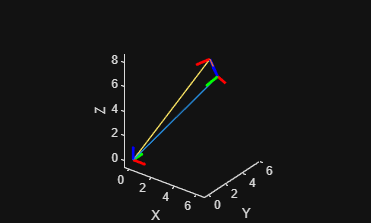


figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe(e(:,:,1),p(:,1))
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded
hold on
plotframe(e(:,:,2),p(:,2))
plotframe(e(:,:,3),p(:,3))
%fr = se3()
plotline([0 0 0],p(:,2)')
plotline(p(:,2)',p(:,3)')
plotline([0 0 0],p(:,3)')


clear e*
clear f*
clear newFrameOrigin
clear p*
clear q

### 2.3 Transformation operator as se3 object and manipulation

using standard vector addition: $^A p = ^ B p + ^A p_{BORG}$, as BORG= B's orgin

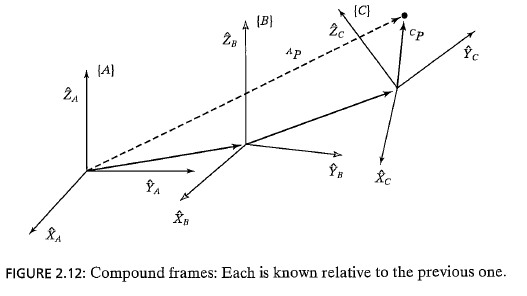

Full homogeneous transform (rotation + translation) is "Transfomed" using the operation(s): ($ ^A_B T$). Note that the most important operation is that it can combine multiple frame relations: $^A_C T = ^A_B T ^B_C T $.

the operation is using the Fig. 2.12, where $^Bp = ^B _C T ^C p$, as $^B _C T = \left[ \matrix{
^B _C R & ^BP_{CORG} \cr
0 & 1
}\right]$, showing that $^B p = ^B_C R ^Cp + ^Bp_{CORG} $, then using the same idea, as $^A_BT = \left[\matrix{
^A_BR & ^Ap_{BORG} \cr
0 & 1
}\right]$, thus it is true that:


$$^A_CT= 
\left[\matrix{
^A_BR^B_CR & ^B_AR^Bp_{CORG}+^Ap_{BORG} \cr
0 & 1
}\right]$$


Now that we're able to draw random frames and locate their relations, we'd be able to acquire how to move around the frame and to attach a robotics model onto the different frames, then later use d-h parameters...

#### Ex 2.3 Using frame transform to find the end effector (EOF) position and orientation representation

given a EOF position, orientation with it's SE3 object, in a random form peof = round(10*rand(3,1)'), rotm_eof

% Define three frame locations, the world frame, end effector frame - (designed to be) based
% on the frame of {B}, then the definition for the frame {B}, at the base
% origin of frame {B} and the actual frame {B} orientation.

% Note that all the rotation matrix (rotm), and the translation vector
% (trvec) are all defined as in world frame.

worldFrame = se3 % eye(4)

worldFrame = se3
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


eofFrame_World = se3(quat2rotm(randrot),round(10*rand(3,1)')) % end effector frame based on world frame

eofFrame_World = se3
   -0.5810    0.7248    0.3703    1.0000
    0.6235    0.6888   -0.3700    2.0000
   -0.5232    0.0159   -0.8521    9.0000
         0         0         0    1.0000


frameB = se3(eul2rotm([0 pi 0]),round(eofFrame_World.trvec*.8)) % frame b orientation and b_original

frameB = se3
   -1.0000         0    0.0000    1.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    7.0000
         0         0         0    1.0000


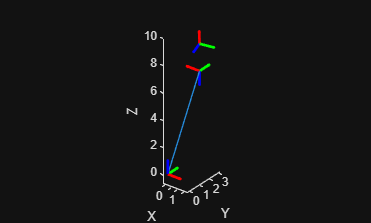


figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe(worldFrame.rotm, worldFrame.trvec)
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded
hold on

plotframe(frameB.rotm, frameB.trvec)
plotframe(eofFrame_World.rotm, eofFrame_World.trvec)
plotline(worldFrame.trvec, frameB.trvec)

In defining and simulation, almost all the actual object, has to be declared in the "world" frame, and in the individual numbering, as like $^A_B R$, $^B_C R$, or $^A p_{1}$, $^Bp_{Aorg}$, all the vectors and matrix are either 3 by 1 and 3 by three, and on appearance its just numbers. One has to be sure how all the referred base frame is rotated and located!!!

% using all the different "world" based se3 object (orientation +
% position), finding the eof "Transformation" object based on frame {B}

!!! Both homogeneous transformation operator ($^A_B T$) and frames = rotation matrix (orientation) + translation vector (position) !!!! can both be used as the se3 object!!! 

% excercise of using object utilites as a frame (orientation + position)
dist(eofFrame_World,frameB)     % find the eucleadean distance between end effector to the frame b base

ans = 2.0236

interp(frameB,eofFrame_World,3) % interpolate points between two "point of orientation"

ans = 1×3 se3 array
ans(1,1) = 

   -1.0000         0    0.0000    1.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    7.0000
         0         0         0    1.0000


ans(1,2) = 

   -0.8888    0.3950    0.2326    1.0000
    0.3681    0.9174   -0.1514    2.0000
   -0.2731   -0.0490   -0.9607    8.0000
         0         0         0    1.0000


ans(1,3) = 

   -0.5810    0.7248    0.3703    1.0000
    0.6235    0.6888   -0.3700    2.0000
   -0.5232    0.0159   -0.8521    9.0000
         0         0         0    1.0000


Using the same se3 object as a standard Homogenous Transform 

rotm(eofFrame_World)

ans =    -0.5810    0.7248    0.3703
    0.6235    0.6888   -0.3700
   -0.5232    0.0159   -0.8521


eofFrame_World * frameB         % multiplication of two "point + orientation" i.e. ^A_B T * ^B_C T 

ans = se3
    0.5810    0.7248   -0.3703    4.4608
   -0.6235    0.6888    0.3700    1.4113
    0.5232    0.0159    0.8521    2.5443
         0         0         0    1.0000


frameB

frameB = se3
   -1.0000         0    0.0000    1.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    7.0000
         0         0         0    1.0000


ans = se3
   -1.0000         0    0.0000    1.0000
         0    1.0000         0    2.0000
   -0.0000         0   -1.0000    7.0000
         0         0         0    1.0000


## Chap 3 Robot manipulator kenematics

Kinematic calculation with DH robot arm setting

### 3.1 D-H parameterization and frame attachment

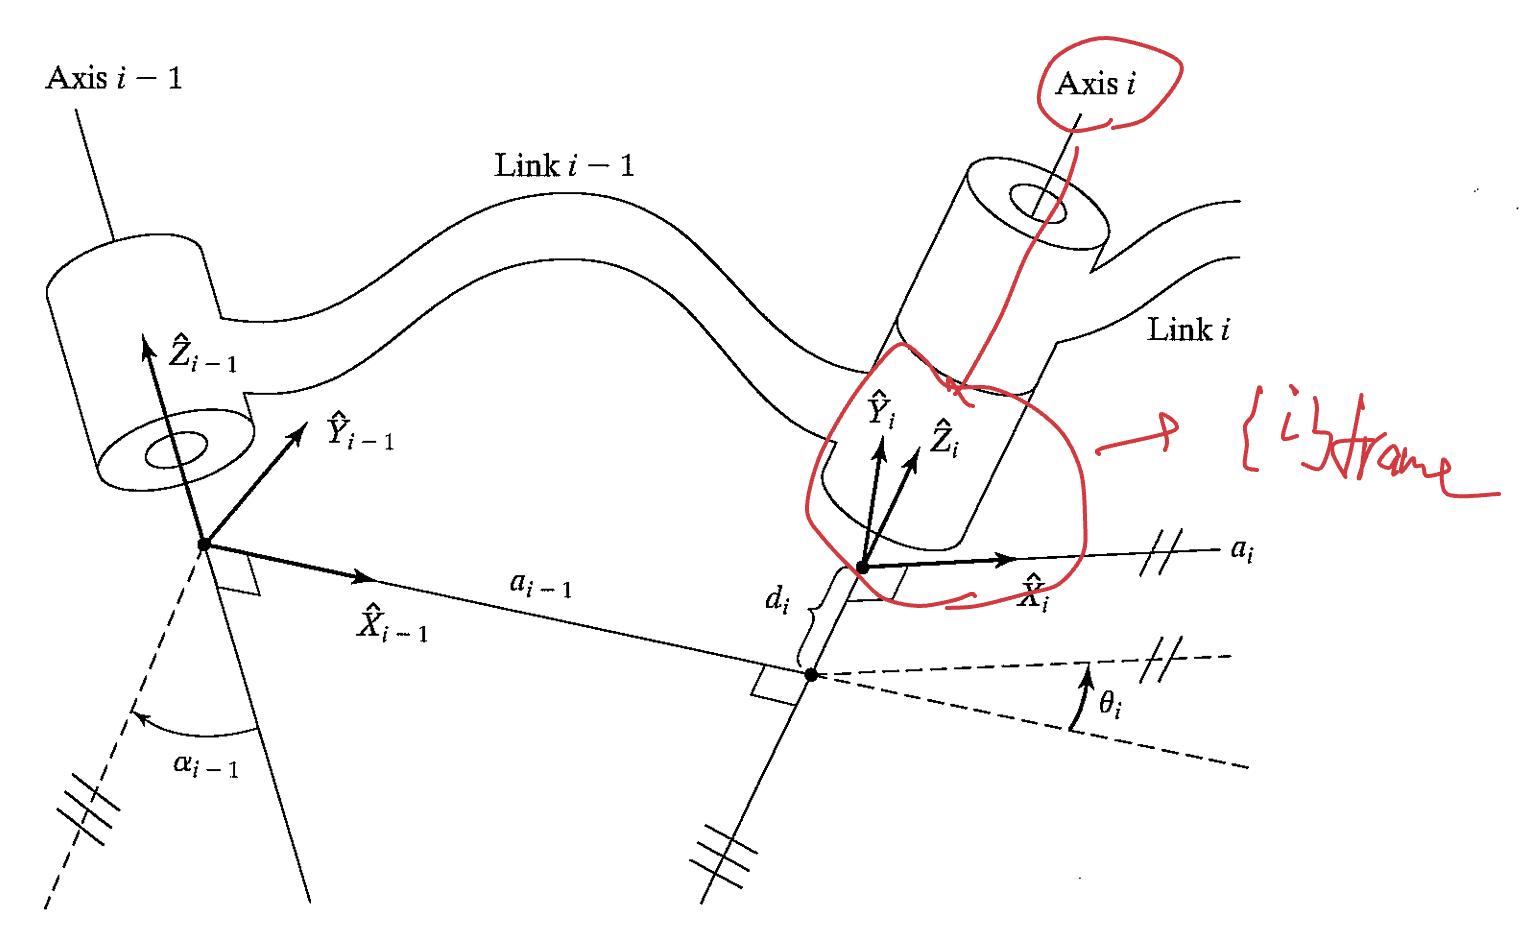

remeber the most important D-H parameters:

- $\alpha_{i-1}$ is the twist angle $\angle z_{i-1}z_i$, rotated about $\hat{x_{i-1}}$, however due to robot linkage, usually $z_{i-1}$ and $z_i$ are often $\pm 90^o (\pm \pi/2)$, as rotational joint or prismatic joint is linked

- $a_{i-1}$ is the link distance $|z_{i-1}z_i|$ along $\hat{x_{i-1}}$, but due to robot joint, usually if we coincide two frames of a joint, is is often zero

- $d_i$ is the link offest $|x_{i-1}x_i|$ along $\hat{z_i}$ as the new link is moved, due to joint movement (rotation/elongation) this is often a parameter!

- $\theta_i$ is the joint angle $\angle x_{i-1}x_i$ about $\hat{z_i}$, and since the most robot is revolute joints, this is often a paremeter!!!

The most important idea here is the linear transformation from the frame $\{i-1\}$ to $\{i\}$ for $^{i-1}_iT$, where we add three additional frames: $\{Q\}, \{R\}, and \{P\} $, such that {Q} is coincide with frame {i-1}, with only rotation $^{i-1}_{Q} T=R_{x_{i-1}}(\alpha_{i-1}) = 
\left[\matrix{
1 & 0 & 0  \cr
0 & c\alpha_{i-1} & -s\alpha_{i-1}  \cr
0 & s\alpha_{i-1} & c\alpha_{i-1} 
}\right]$, and $^{Q}_{R}T=D_{x_{i-1}}(a_{i-1})=^QP_{org}+\left[\matrix{
a_{i-1}x \cr
a_{i-1}y \cr
a_{i-1}z
}\right]
$

## Appendix A:Used Functions

### Function 1: 

homogenious transform $^A_BT = \left[\matrix{
^A_BR & ^Ap_{Borg} \cr
0..0 & 1
}\right]$, using MatLab robotics toolbox

% Use MATLAB robotics toolbox's transform: se2, se3, so2, so3... and so
% on...

### Function 2:

a function to draw line of vector from HEAD to TAIL

function varargout = plotline( startPoint, endPoint)

%PLOTLINE Plot a 3-D Cartesian line between two points.
%     plotframe( )
%     plotframe( startPoint, endPoint )
%     plotframe( startPoint, endPoint, basisVectorLengths )
%     plotframe( __ , Parent=ax )
%     plotframe( __ , Name=Value )
%     hg = plotframe( __ )
% 
%   INPUTS
%   - startPoint        Defines the origin of the line. Default is zero zero
%                           , i.e., [0 0 0]. 
%   - endPoint          Defines the position of end of line 
%                           the origin. 1-by-3 or 3-by-1 numeric vector.
%                           Default is [1 1 1].
%   - basisVectorLengths    Length to plot each arrow (basis) of the
%                           coordinate frame. Scalar, 1-by-3, or 3-by-1 
%                           numeric vector. Default is 1.
%   - Name-Value Arguments
%       + Parent            Axes in which to plot. Scalar axes, group 
%                           (hggroup), or transform (hgtransform) object.
%                           Default is the current axes (gca).
%       + UpdateFrame       With UpdateFrame, the passed plot handles
%                           will be updated with the current parameters, 
%                           rather than creating a new plot. This is more 
%                           efficient and convenient for moving frames.
%                           Handle to an existing frame plot, outputted
%                           from a previous call to plotframe.
%       + MatrixIndexing    Depending on notation, either the columns or 
%                           the rows of rotationMatrix define the 
%                           orientation of the basis vectors. Text scalar, 
%                           either "columnmajor" or "rowmajor". Default is 
%                           row-major.
%       + LabelBasis        Whether the bases should be labelled, e.g., 
%                           "X", "Y", and "Z". Scalar logical. Default is 
%                           false.
%       + Labels            Text with which to label each basis, if 
%                           LabelBasis is enabled. Scalar, 1-by-3, or 
%                           3-by-1 text vector. Default is {'X','Y','Z'}.
%       + BasisColors       Color for each basis vector. Any color format
%                           accepted by MATLAB can be used, e.g., RGB 
%                           triplet [0 0 0], hexadecimal color code 
%                           #000000, or color name 'black' or 'k'. Specify
%                           multiple colors with an M-by-3 matrix where 
%                           each RGB color is a row, or as a 1-by-3 or 
%                           3-by-1 text array. Default is {'r','g','b'}.
%       + TextProperties    Custom properties for the basis labels. 
%                           Name-value arguments stored in a cell array of 
%                           alternating text property names and values, 
%                           e.g., {'FontSize',20,'FontWeight','bold'}.
%       + QuiverProperties  Additional name-value arguments are passed as
%                           properties of the Quiver charts used to plot 
%                           the basis vectors, e.g.,
%                           plotframe( LineStyle="-.", Marker="o" ).
%   OUTPUTS
%   - hg                    Group object (hggroup) containing handles to  
%                           the constituent parts of the coordinate frame 
%                           plot, i.e., the 3 Quiver and optional Text 
%                           objects.
% 
% 
%   See also QUIVER3, QUAT2ROTM, EUL2ROTM, MAKEHGTFORM, PLOTCAMERA

    arguments
        startPoint (1,3) double = [ 0, 0, 0]
        endPoint (1,3) double = [ 1, 1, 1 ]
    end
    
    %axis off
    x = [startPoint(1) endPoint(1)];
    y = [startPoint(2) endPoint(2)];
    z = [startPoint(3) endPoint(3)];
    line(x,y,z)
    drawnow

end